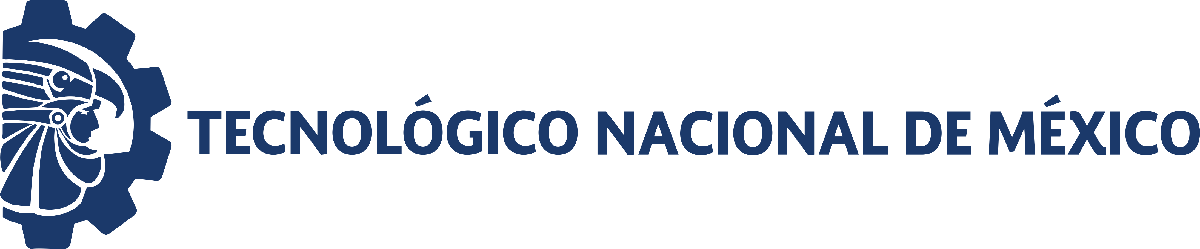                                 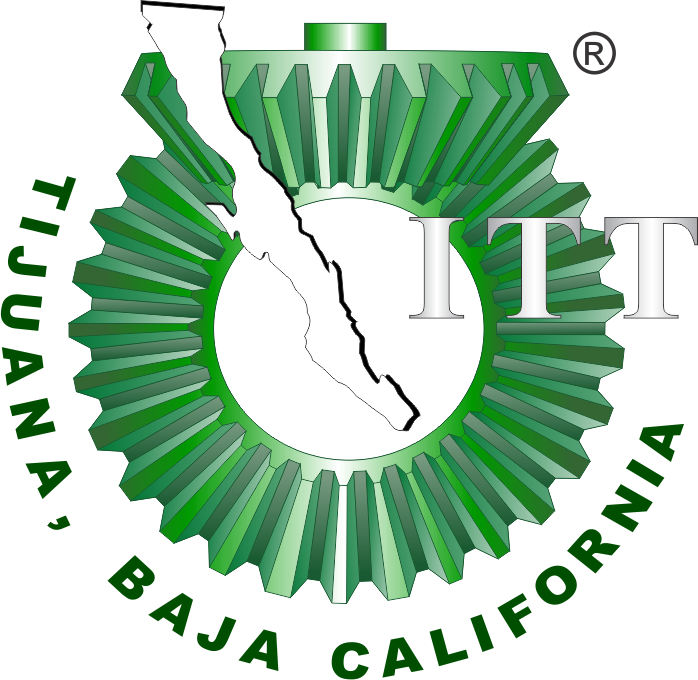

# Práctica : Regeneración de glóbulos rojos

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general                                                                                                            

                                                                                                         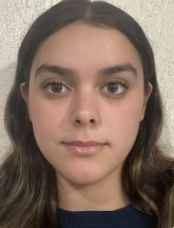

Nombre del alumno: Anette Mariana Vidal Ortiz

Número de control: 22212389

Correo institucional: L22212389**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; format short; warning('off','all')
tend = 180; %Tiempo de la simulación en días
dt = 1E-3; %Intervalo de integración para el método de solución por diferencias finitas
n = round(tend/dt); %Cantidad de iteraciones para el método numérico

%Condiciones iniciales base para cada paciente
x1_0 = 59; x2_0 = 44; x3_0 = 885;

%Parámetros particulaes para cada paciente
gamma = [0.769; 0.388; 0.510; 0.590; 0.262; 0.324; 0.356; 0.089; 0.243; 0.057];
beta = [1.650; 0.867; 1.167; 2.615; 1.518; 2.676; 0.891; 2.557; 0.925; 0.879];

seed = 22212389; %Semilla para asegurar reproducibilidad
rng(seed, "twister")
%Intervalo de las condiciones iniciales
xmin = 0.99; xmax= 1.01;
interval = xmin + (xmax - xmin).*rand(numel(gamma),1);

%Condiciones iniciales para cada paciente
x1_0 = x1_0*interval; disp('x1(0) = '); disp(x1_0');...
x2_0 = x2_0*interval; disp('x2(0) = '); disp(x2_0');...
x3_0 = x3_0*interval; disp('x3(0) = '); disp(x3_0');

x1(0) = 
   58.9008   59.4718   59.2174   59.3530   59.1184   58.7647   58.8552   58.7344   59.2322   58.6968



x2(0) = 
   43.9260   44.3519   44.1621   44.2632   44.0883   43.8245   43.8920   43.8019   44.1731   43.7739



x3(0) = 
  883.5115  892.0771  888.2611  890.2944  886.7757  881.4708  882.8282  881.0154  888.4826  880.4520



## Caso: Sin transfusión sanguínea [u(t)=0]

u = zeros(n+1,1); %No hay transfusión
fig = 1;
for i = 1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## Caso: Con transfusión sanguínea [u(t)= 1 [t1,t2]]

u = zeros(n+1,1);%Hay transfusión
    for i = 1:1000
     u(i)=1;
    end
fig = 2;
for i = 1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## Funcion : Modelo matemático

$\dot{x_{1\;} }$= $\beta \left(X_0 -k_{1\textrm{x1}} \right)+\frac{\gamma \left(B_{\textrm{ase}} -x_3 \right)\left(1-u\left(t\right)\right)x_1 }{B_{\textrm{ase}} }$

$\dot{x_2 }$ = $\beta \left(k_1 x_1 -k_2 x_2 \right)$

$\dot{x_3 }$ = $\beta \left(k_2 x_2 -ax_3 \right)-u\left(t\right)x_3$

function [t,x1,x2,x3] = system(x1_0,x2_0,x3_0,beta,gamma,u,dt,tend)
%Parámetros fijos del sistema
Base = 885.42; X0 = 7.3785; k1 = 0.125; k2 = 0.1667; alpha = 0.00833;
t = (0:dt:tend)';
n = round (tend/dt);
x1 = zeros (n+1,1); x1(1) = x1_0;
x2 = zeros (n+1,1); x2(1) = x2_0;
x3 = zeros (n+1,1); x3(1) = x3_0;

    for i = 1:n
     x1(i+1) = x1(i) + (beta*(X0 - k1*x1(i)) + gamma*(Base - x3(i))*(1-u(i))*x1(i)/Base)*dt;
     x2(i+1) = x2(i) + (beta*k1*x1(i) - k2*x2(i))*dt;
     x3(i+1) = x3(i) + (beta*(k2*x2(i) - alpha*x3(i)) - u(i)*x3(i))*dt;
    end
end

## Funcion : Soluciones en el tiempo

$\dot{x_{1\;} }$= $\beta \left(X_0 -k_{1\textrm{x1}} \right)+\frac{\gamma \left(B_{\textrm{ase}} -x_3 \right)\left(1-u\left(t\right)\right)x_1 }{B_{\textrm{ase}} }$

$\dot{x_2 }$ = $\beta \left(k_1 x_1 -k_2 x_2 \right)$

$\dot{x_3 }$ = $\beta \left(k_2 x_2 -ax_3 \right)-u\left(t\right)x_3$

function plotdata(t,x1,x2,x3,fig)
    set(figure(fig), 'color','w')
    set(gcf,'Units','Centimeters','Position',[1,1,20,20])
    mycolors = [145,18,188;
        0,128,157;
        120,157,188;
        203,4,4;
        125,150,117;
        0,0,1;
        255,143,143;
        255,241,203;
        194,226,250;
        183,163,227]/255; %colorhunt.co

    subplot(3,1,1)
    hold on; grid off; box on; colororder(mycolors)
    plot(t,x1)
    xlabel('$t$ $[days]$', 'Interpreter','latex','FontSize',10)
    ylabel('$x_1(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
        'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca, 'FontName','Times New Roman','FontSize',10)

    subplot(3,1,2)
    hold on; grid off; box on;colororder(mycolors)
    plot(t,x2)
    xlabel('$t$ $[days]$', 'Interpreter','latex','FontSize',10)
    ylabel('$x_2(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
        'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca, 'FontName','Times New Roman','FontSize',10)

    subplot(3,1,3)
    hold on; grid off; box on;colororder(mycolors)
    plot(t,x3)
    xlabel('$t$ $[days]$', 'Interpreter','latex','FontSize',10)
    ylabel('$x_3(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
        'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca, 'FontName','Times New Roman','FontSize',10)

    if fig == 1
        exportgraphics(gcf,'Caso Sin transfusión.pdf','ContentType','Vector')
    elseif fig == 2
        exportgraphics(gcf,'Caso Con transfusión.pdf','ContentType','Vector')
    end
end
